%%Question1

clear all; close all; clc;
%%%%% OFDM parameters %%%%%
params.del_f = 1e4;              % subcarrier spacing = 10kHz
params.numCarriers = 512;        % fft size = 512
params.prefixDuration = 6.25e-6; % CP duration =6.25 mus

params.sampleRate = params.del_f * params.numCarriers;
params.prefixLength = round(params.prefixDuration * params.sampleRate);
params.blockDuration = (params.numCarriers + params.prefixLength) / params.sampleRate;
params.preamblePeriodicity = 5;               % Frame size = 5
params.guardTones = [241:256 -255:-241];   % Guard bands
params.DCSubcarrier = [0];                   % DC carrier
params.pilots = false;
params.pilotPeriodicity = 8;

%%%%% Channel Parameters %%%%%
params.pathGains = [-3 0 -1 -4 -9 -17];
params.delays = [0 7 13 18 21 26];
params.CFO = 28.65e2;                      % Maximum offset = 28.65kHz
% params.CFO = 0;                      % Maximum offset = 28.65kHz
params.SNR =10;

%%%%% Modulation parameters %%%%%
params.modulationType = 'QAM';
params.modulationOrder = 16;
params.numFrames = 10;

% params.numCarriers = 16;
% params.prefixLength = 4;  
% params.guardTones = [-7:-6 7:8];

S = OFDM.generateOFDMframe(params);
s = OFDM.modulate(S, params);
[r, h] = OFDM.channel(s, params);

f_est = OFDM.estimateCFO(r, params);

err = f_est - params.CFO;
mse = mean(abs(err).^2)   % mean handles scalar or vector f_est

mse = 7.5973e+03

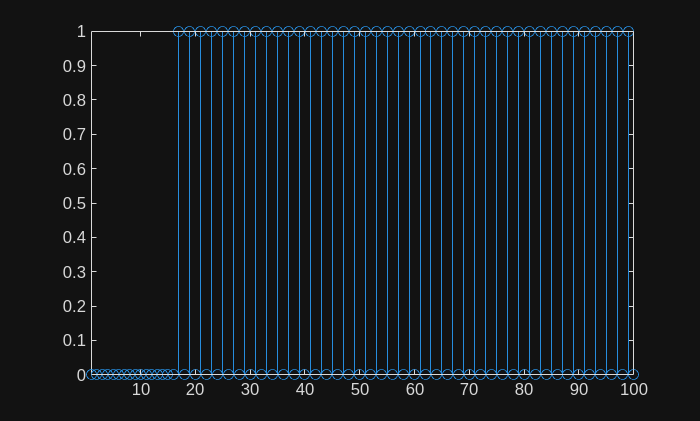

N = params.numCarriers;
Lcp = params.prefixLength;

figure; stem(abs(S(:, 1)))
xlim([1 100])

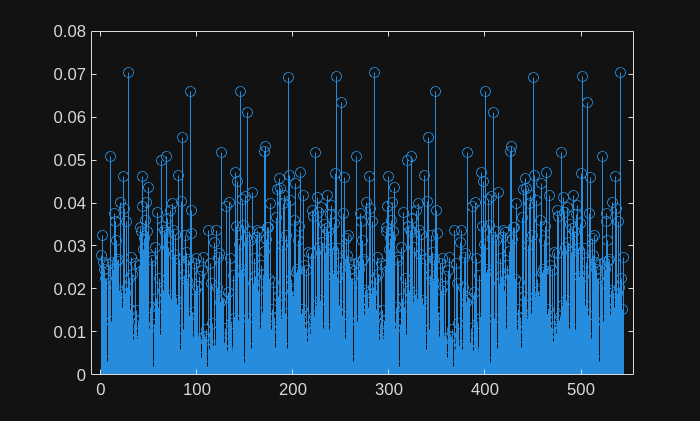

s1 = s(1: N+Lcp);
figure; stem(abs(s1))

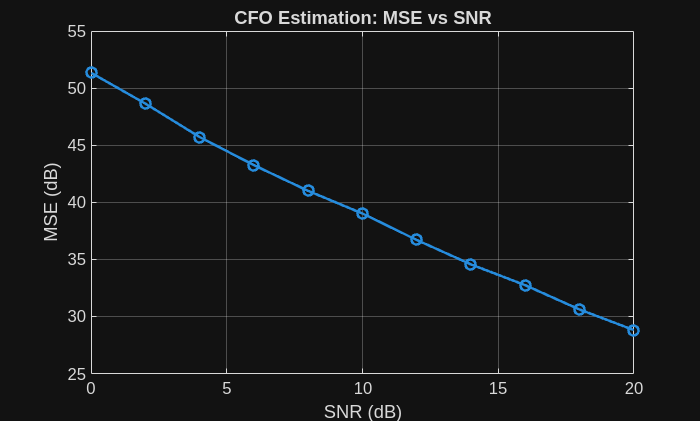


%% SNR vs MSE plot

snrDbVec = 0:2:20;
numTrials = 200; % increase for smoother curve

mse = zeros(size(snrDbVec));

for k = 1:numel(snrDbVec)
	params.SNR = snrDbVec(k);

	se_trials = zeros(numTrials, 1); % squared error per trial

	for t = 1:numTrials
		S = OFDM.generateOFDMframe(params);
		s = OFDM.modulate(S, params);
		r = OFDM.channel(s, params);

		f_est = OFDM.estimateCFO(r, params); % returns vector (per preamble)
		err = f_est - params.CFO;
		se_trials(t) = mean(abs(err).^2);    % average if f_est is a vector
	end

	mse(k) = mean(se_trials);
end

mseDb = 10*log10(mse);

figure;
plot(snrDbVec, mseDb, '-o', 'LineWidth', 1.5);
grid on;
xlabel('SNR (dB)');
ylabel('MSE (dB)');
title('CFO Estimation: MSE vs SNR');

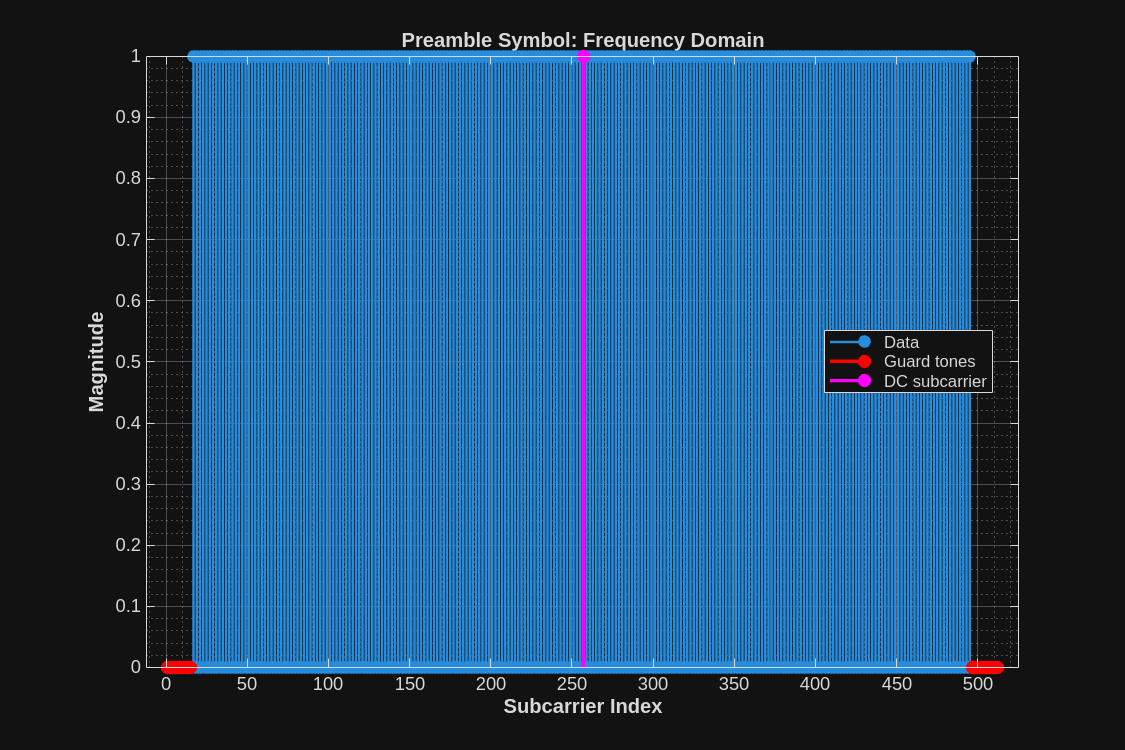

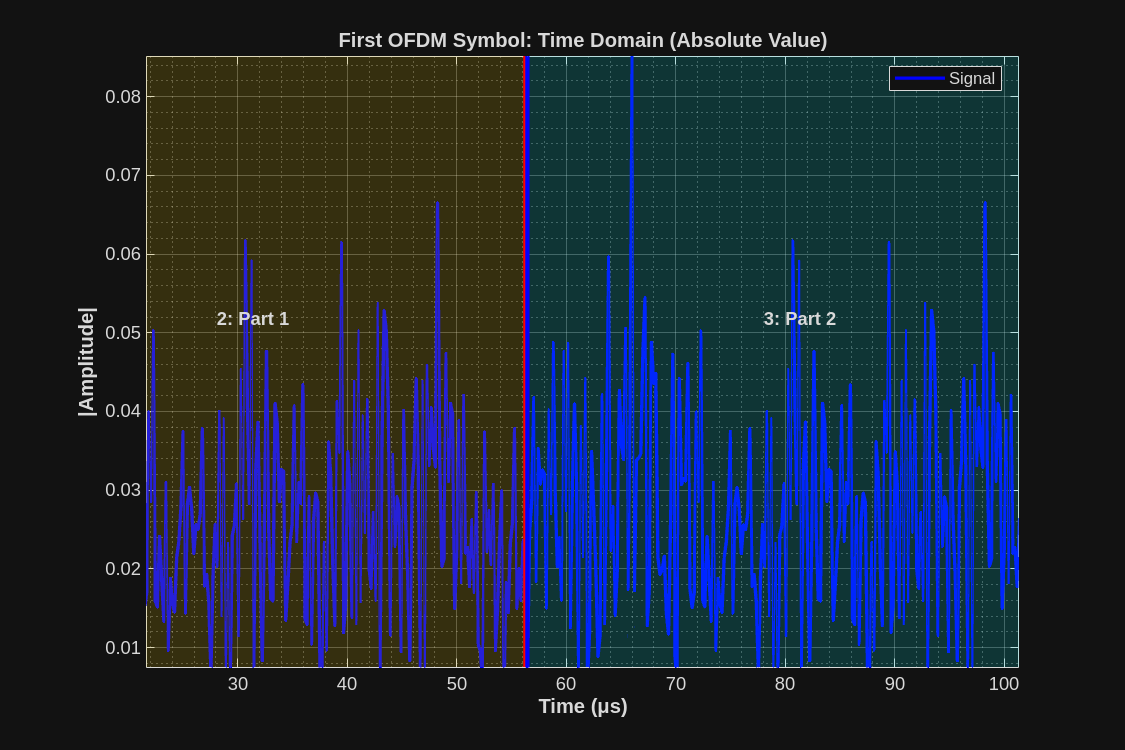

Error using matlab.graphics.shape.TextBox
Error setting property 'BackgroundColor' of class 'TextBox':
Invalid color name or hexadecimal color code. Valid names include: 'red', 'green', 'blue', 'cyan', 'magenta', 'yellow', 'black', 'white', and 'none'. Valid hexadecimal color codes consist of '#' followed by three or six hexadecimal digits.

Error in annotation (line 143)
        h = matlab.graphics.shape.TextBox(aargs{:});
        ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^
Error in 

plot_preamble_analysis()